# Phase response for fixed C

Expecting four evenly spaced events, equally. Plots are based on the assumption that each event is reached with identical phase uncertainty.

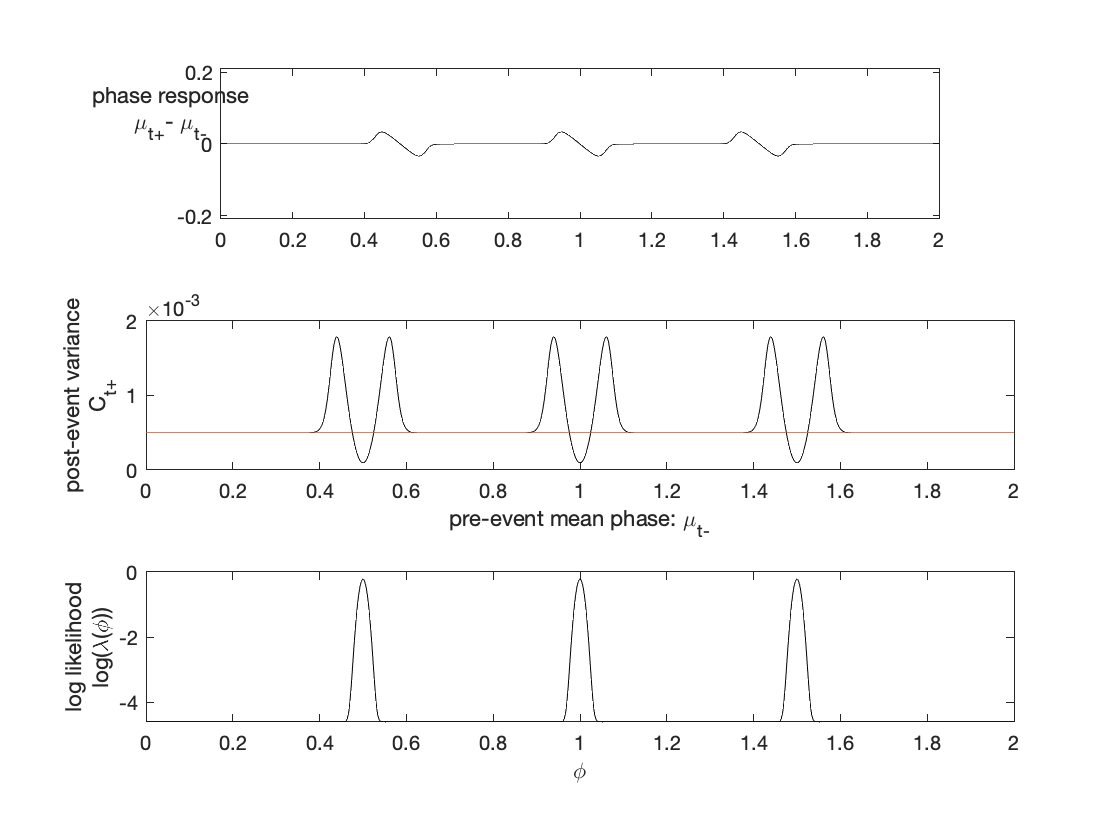

params = PIPPET_params(...
    'events_unit', [.5],...
    'expected_period', .5,...
    'variance_unit', [.0001],...
    'lambda_unit', [.02],...
    'expected_cycles', 3,...
    'event_times', event_times,...
    'title', 'Swung rhythm');

% lambda_0 = .00000001;
x_list = 0:.002:2;

C = .0005;
mu_list = zeros(size(x_list));
C_list = zeros(size(x_list));
for i = 1:length(x_list)
    mu_list(i) = params.streams{1}.mu_star(x_list(i), C);
    C_list(i) = params.streams{1}.C_star(x_list(i), C);
end

PRC = mu_list - x_list;

figure()
subplot(3,1,1)
plot(x_list, PRC, 'k')
xlim([min(x_list), max(x_list)])
%axis equal
ylabel({'phase response';'\mu_{t+}- \mu_{t-}'})
axis('equal')
set(get(gca, "YLabel"), 'Rotation', 0)

subplot(3,1,2)
plot(x_list, C_list, 'k')
hold on
plot(x_list, zeros(size(x_list))+C)
ylabel({'post-event variance';'C_{t+}'})
xlabel({'pre-event mean phase: \mu_{t-}'})
%set(get(gca, "YLabel"), 'Rotation', 0)

subplot(3,1,3)
plot(x_list, log(params.streams{1}.expect_func(x_list)), 'k')
ylabel({'log likelihood';'log(\lambda(\phi))'})
xlabel('\phi')

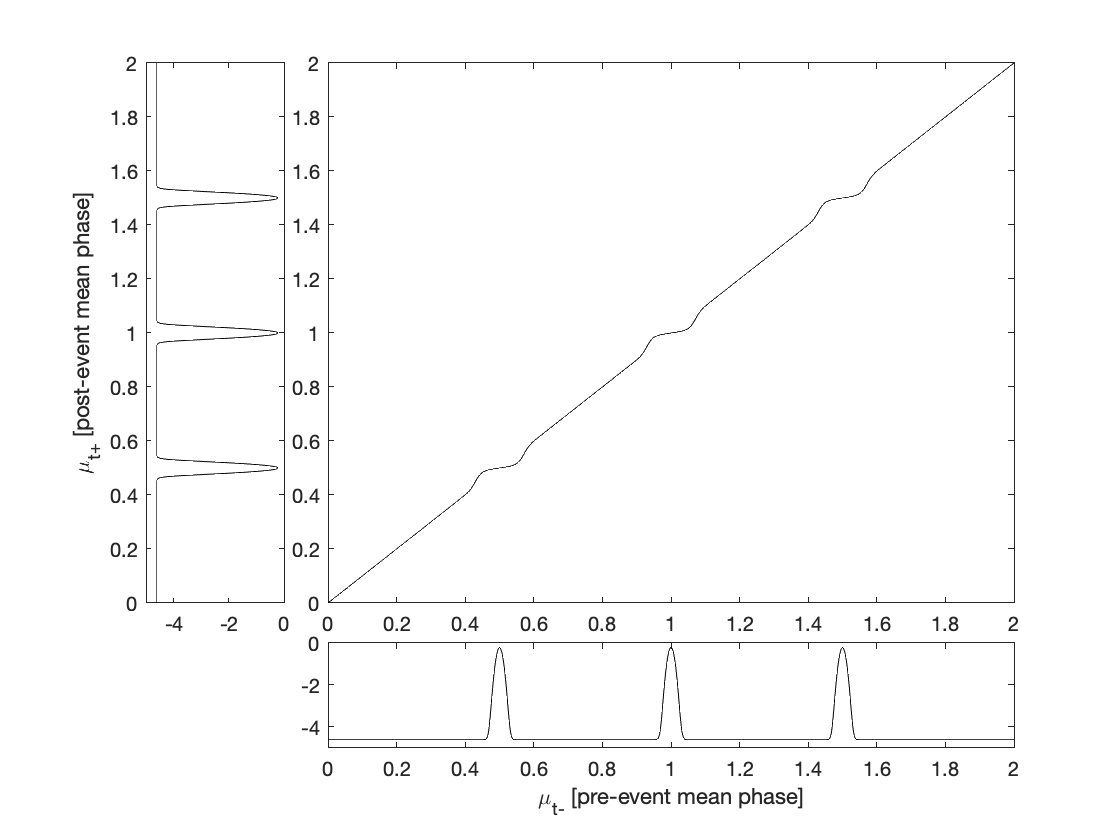

%set(get(gca, "YLabel"), 'Rotation', 0)

figure()
title('Phase Transition Curve (PTC)')
subplot(5,5, [2,3,4,5, 7,8,9,10, 12,13,14,15, 17,18,19,20])
plot(x_list, mu_list, 'k')
xlim([min(x_list), max(x_list)])
ylim([min(x_list), max(x_list)])

subplot(5,5, [1,6,11,16])
plot(log(params.streams{1}.expect_func(x_list)), x_list, 'k')
ylabel('\mu_{t+} [post-event mean phase]')

subplot(5,5, [22,23,24,25])
plot(x_list, log(params.streams{1}.expect_func(x_list)), 'k')
xlabel('\mu_{t-} [pre-event mean phase]')

## Phase response for several Cs

A single event is expected. Plots are based on the assumption that phase uncertainty grows steadily over the course of a silent interval. As a result, the phase response curve shows a more extreme correction for longer intervals.

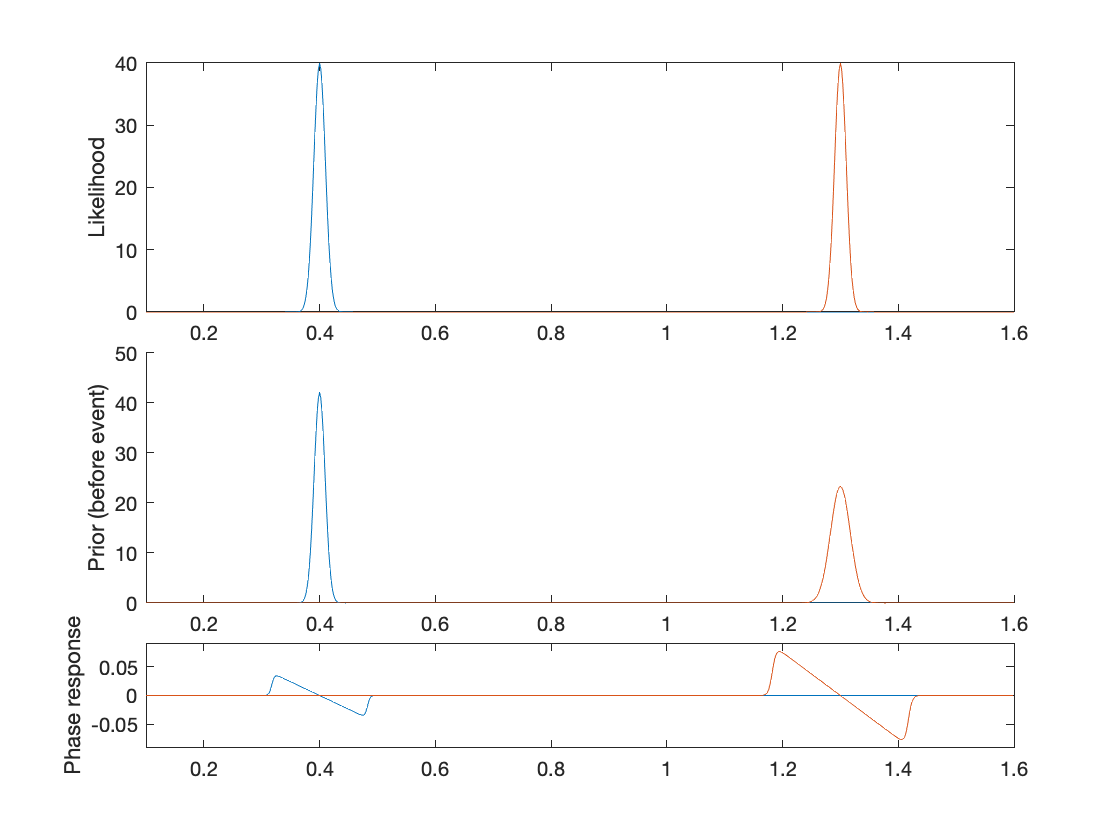


params = PIPPET_params(...
    'events_unit', [.5],...
    'expected_period', .5,...
    'variance_unit', [.0001],...
    'lambda_unit', [.02],...
    'expected_cycles', 3,...
    'event_times', event_times,...
    'title', 'Swung rhythm');

gauss_distribution = @(x, mean, v) exp(-.5 * ((x - mean).^ 2) ./ v)./ (sqrt(2*pi*v));

sigma = 0.015;

x_list = 0.1:.002:1.6;

e_vars = .0001*[1];
e_lambdas = [.02];
lambda_0 = .00000001;

e_means = [.4];

mu_i_list = @(mu, C) (mu/C + e_means./e_vars)./(1/C + 1./e_vars);
C_i_list = @(C) 1./(1/C + 1./e_vars);
Lambda_i_list = @(mu, C) e_lambdas .* gauss_distribution(mu, e_means, e_vars+C);
Lambda_star = @(mu, C) lambda_0 + sum(Lambda_i_list(mu, C));
mu_star = @(mu, C) (lambda_0*mu + sum(Lambda_i_list(mu, C) .* mu_i_list(mu,C)))/Lambda_star(mu,C);
C_star= @(mu,C) (lambda_0*C + sum(Lambda_i_list(mu, C) .* (C_i_list(C) + (mu_i_list(mu, C)-mu).^2)))/Lambda_star(mu,C);

C1 = sigma^2 * .4;
mu_list = zeros(size(x_list));
C_list = zeros(size(x_list));
for i = 1:length(x_list)
    mu_list(i) = mu_star(x_list(i), C1);
    C_list(i) = C_star(x_list(i), C1);
end

e_means = [1.3];

mu_i_list = @(mu, C) (mu/C + e_means./e_vars)./(1/C + 1./e_vars);
C_i_list = @(C) 1./(1/C + 1./e_vars);
Lambda_i_list = @(mu, C) e_lambdas .* gauss_distribution(mu, e_means, e_vars+C);
Lambda_star = @(mu, C) lambda_0 + sum(Lambda_i_list(mu, C));
mu_star = @(mu, C) (lambda_0*mu + sum(Lambda_i_list(mu, C) .* mu_i_list(mu,C)))/Lambda_star(mu,C);
C_star= @(mu,C) (lambda_0*C + sum(Lambda_i_list(mu, C) .* (C_i_list(C) + (mu_i_list(mu, C)-mu).^2)))/Lambda_star(mu,C);

C2 = sigma^2 * 1.3;
mu_list_2 = zeros(size(x_list));
C_list_2 = zeros(size(x_list));
for i = 1:length(x_list)
    mu_list_2(i) = mu_star(x_list(i), C2);
    C_list_2(i) = C_star(x_list(i), C2);
end

PRC = mu_list - x_list;

PRC_2 = mu_list_2 - x_list;

figure()
subplot(5,1, 1:2)
plot(x_list, gauss_distribution(x_list, .4, e_vars(1))+lambda_0);
hold on
plot(x_list, gauss_distribution(x_list, 1.3, e_vars(1))+lambda_0)
xlim([min(x_list), max(x_list)])
ylabel('Likelihood')

subplot(5,1, 3:4)
hold on
plot(x_list, gauss_distribution(x_list, .4, C1));
plot(x_list, gauss_distribution(x_list, 1.3, C2));
xlim([min(x_list), max(x_list)])
ylabel('Prior (before event)')

subplot(5,1,5)
plot(x_list, PRC)
hold on
plot(x_list, PRC_2)
xlim([min(x_list), max(x_list)])
axis equal
ylabel('Phase response')


% subplot(3,1,3)
% plot(x_list, C_list)
% hold on
% plot(x_list, C_list_2)
% plot(x_list, zeros(size(x_list))+C)
% plot(x_list, zeros(size(x_list))+C2)
% ylabel('post-event variance')
% xlabel('event phase')

## Phase response as function of period

Same as above, but for a range of different silent intervals. Roughly reproduces the more extreme phase corrections observed for longer intervals (in, e.g., Repp, Keller, & Jacoby 2012)

gauss_distribution = @(x, mean, v) exp(-.5 * ((x - mean).^ 2) ./ v)./ (sqrt(2*pi*v));

e_means = [0];
e_vars = .0001*[1];
e_lambdas = [.02];
lambda_0 = .005;

% if wrap
%     e_means = [e_means - 1, e_means, e_means+1];
%     e_vars = [e_vars, e_vars, e_vars];
%     e_lambdas = [e_lambdas, e_lambdas, e_lambdas];
% end

mu_i_list = @(mu, C) (mu/C + e_means./e_vars)./(1/C + 1./e_vars);
C_i_list = @(C) 1./(1/C + 1./e_vars);
Lambda_i_list = @(mu, C) e_lambdas .* gauss_distribution(mu, e_means, e_vars+C);
Lambda_star = @(mu, C) lambda_0 + sum(Lambda_i_list(mu, C));
mu_star = @(mu, C) (lambda_0*mu + sum(Lambda_i_list(mu, C) .* mu_i_list(mu,C)))/Lambda_star(mu,C);
C_star= @(mu,C) (lambda_0*C + sum(Lambda_i_list(mu, C) .* (C_i_list(C) + (mu_i_list(mu, C)-mu).^2)))/Lambda_star(mu,C);


sigma = 0.015;

period_list = [.4, .7, 1, 1.3];

template = zeros(length(x_list));

Unrecognized function or variable 'x_list'.

for i = 1:length(e_means)
    template = template + e_lambdas(i)*gauss_distribution(x_list, e_means(i), e_vars(i))';
end
template = template + lambda_0;

delta = .01;
slope_list = zeros(size(period_list));

for i = 1:length(period_list)
    C = sigma^2 * period_list(i);
    mu_1 = mu_star(0-delta, C);
    mu_2 = mu_star(0+delta, C);
    slope_list(i) = 1-(mu_2)/delta;;
end

figure()
plot(period_list, slope_list, 'o-')
ylabel('\alpha')
xlabel('period')
ylim([0, 1.4])
xlim([.1, 1.6])

## Time warping

What happens with strong expectations when nothing happens, as compared to when expectations are met? Time dilation!

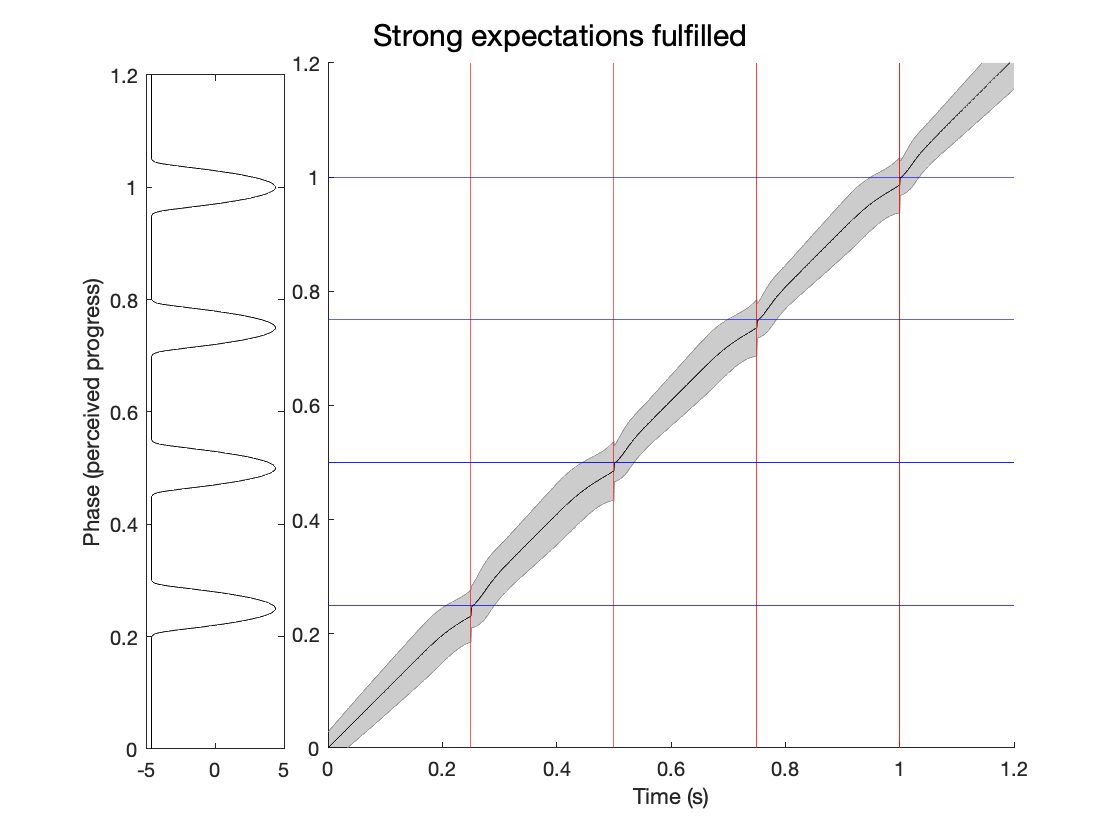



params = PIPPET_params(...
    'lambda_unit', 100*0.02,...
    'event_times',[.25, .5,.75, 1],...
    'title', 'Strong expectations fulfilled');
[mu_list, C_list] = run_PIPPET(params);

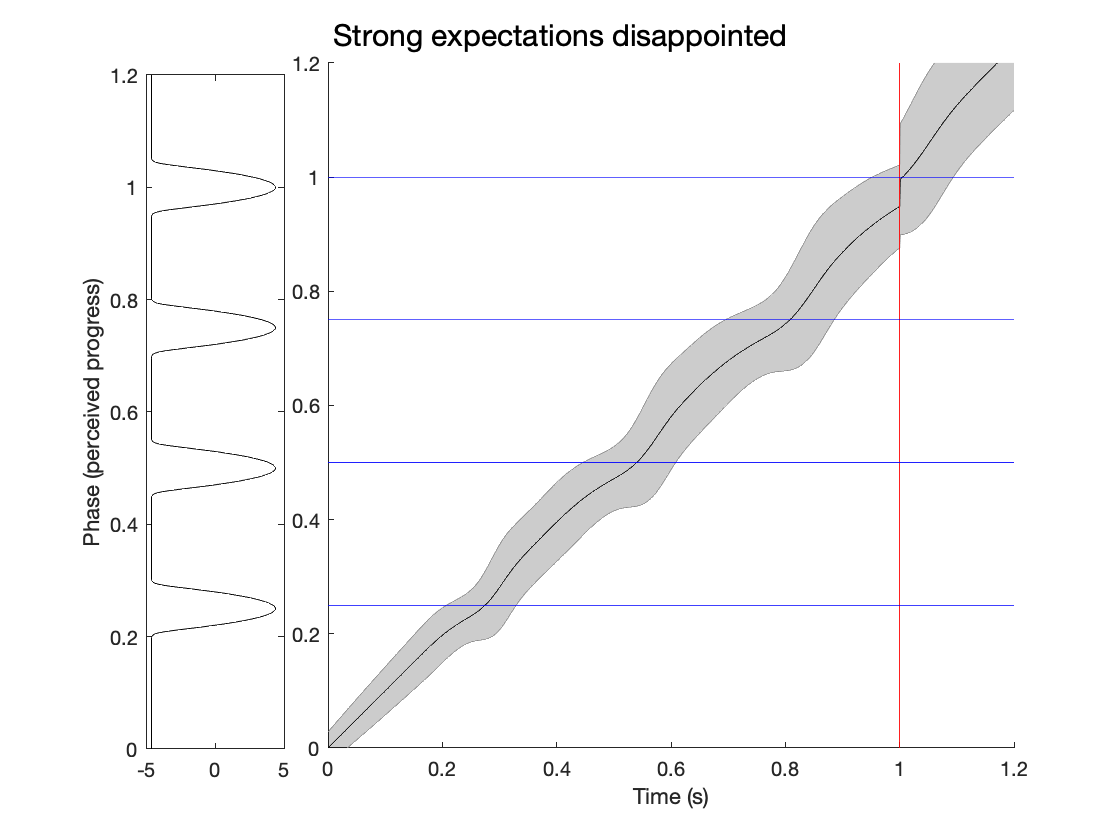


params2 = PIPPET_params(...
    'lambda_unit', 100*0.02,...
    'event_times',[1],...
    'title', 'Strong expectations disappointed');

[mu_list, C_list] = run_PIPPET(params2);

## Swingin'

The filter detects and adjusts to a phase shift in a swung rhythm.

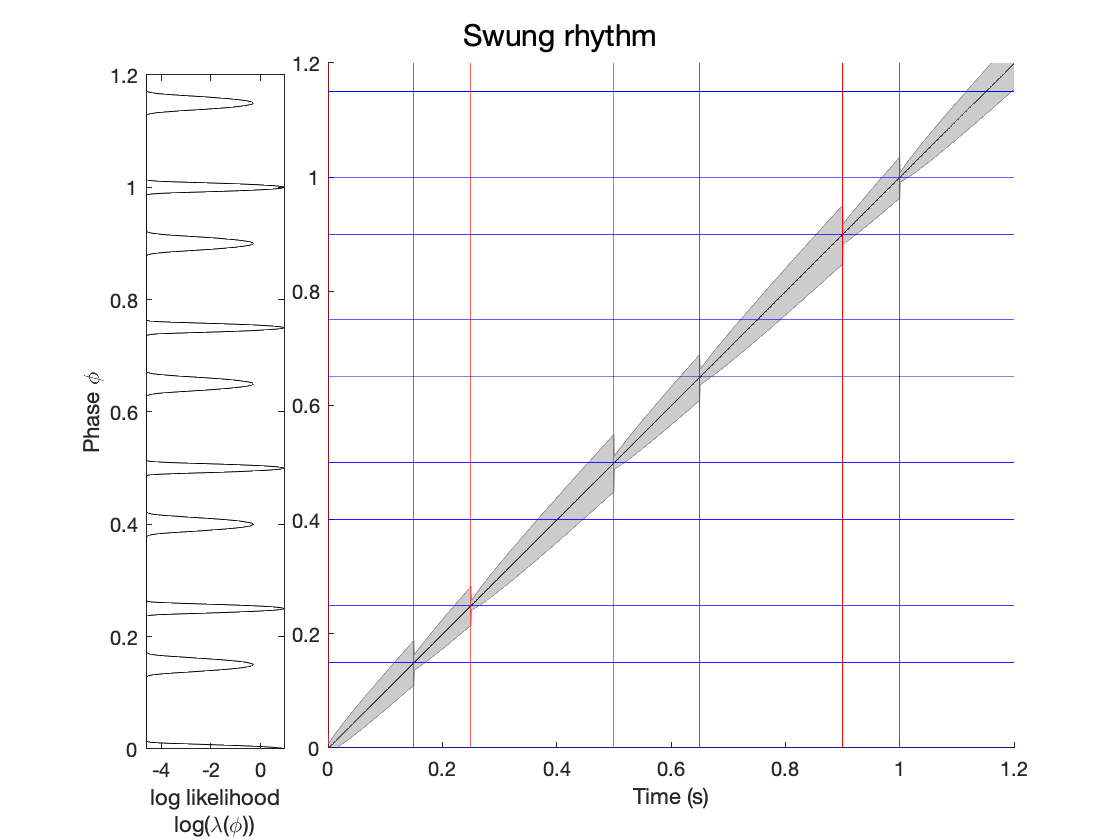

event_times = [0, 0.150, 0.2500, 0.5000, 0.650, 0.900, 1.0000];


params = PIPPET_params(...
    'events_unit', [0, .15],...
    'variance_unit', [.00001, .00003],...
    'lambda_unit', [.02, .01],...
    'expected_cycles', 5,...
    'event_times', event_times,...
    'title', 'Swung rhythm');

[mu_list, C_list] = run_PIPPET(params);

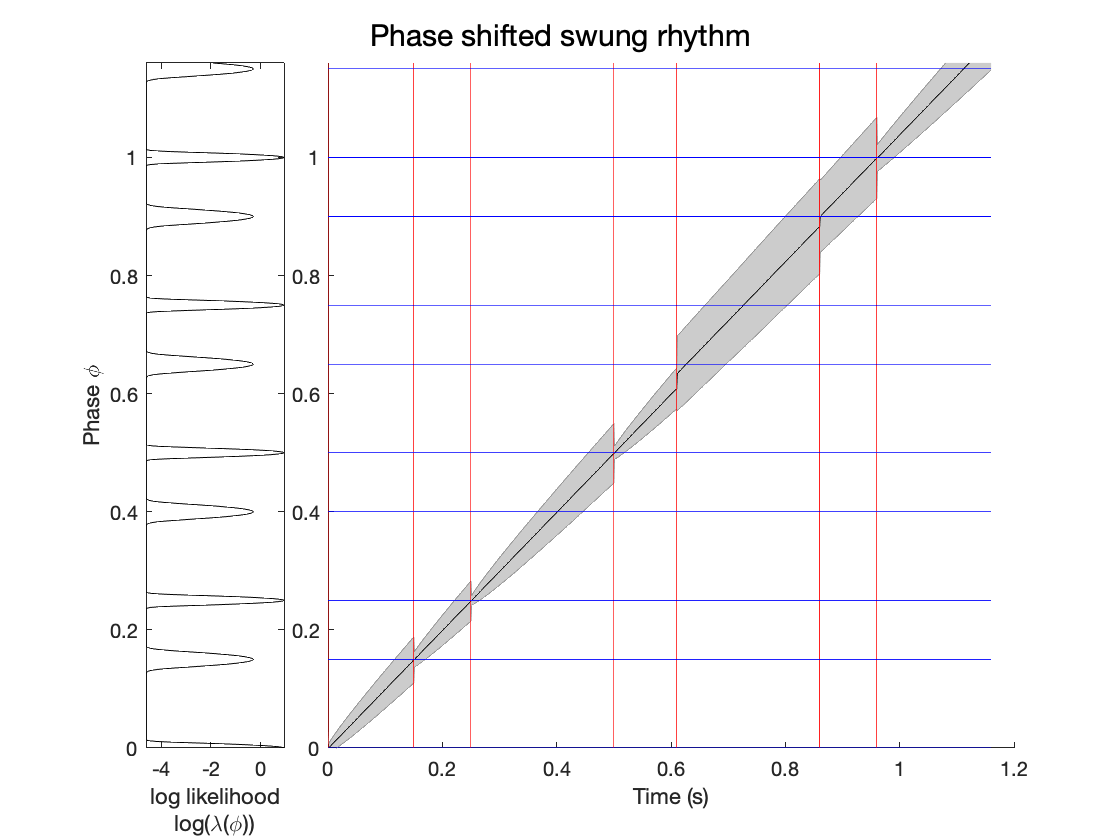


event_times(5:end)=event_times(5:end)-.04;

params = PIPPET_params(...
    'events_unit', [0, .15],...
    'variance_unit', [.00001, .00003],...
    'lambda_unit', [.02, .01],...
    'expected_cycles', 5,...
    'event_times', event_times,...
    'title', 'Phase shifted swung rhythm');

[mu_list, C_list] = run_PIPPET(params);

## Confused

If expected timing of subdivisions is not sufficiently precise, swung and syncopated rhythms can be confusing!

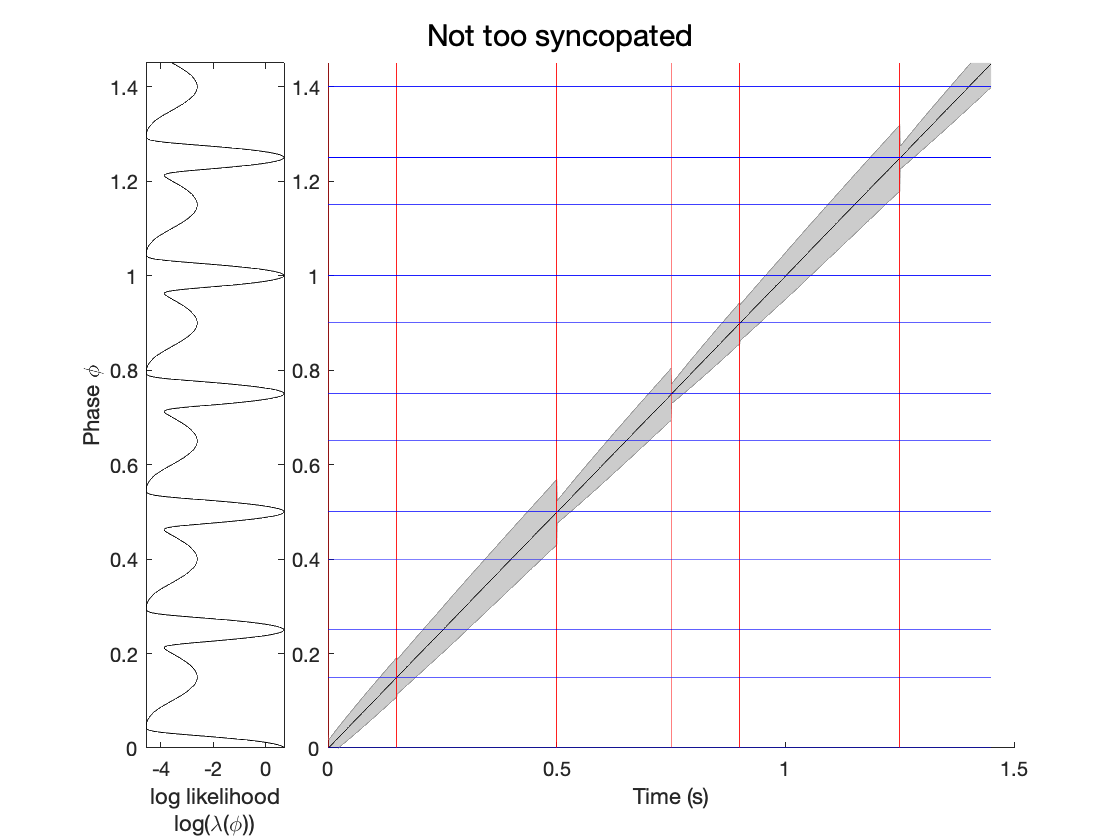

event_times = [0, 0.150, .5, .75, .9, 1.25];

params = PIPPET_params(...
    'events_unit', [0, .15],...
    'variance_unit', [.0001, .001],...
    'lambda_unit', [.05, .005],...
    'expected_cycles', 6,...
    'event_times', event_times,...
    'title', 'Not too syncopated');
[mu_list, C_list] = run_PIPPET(params);

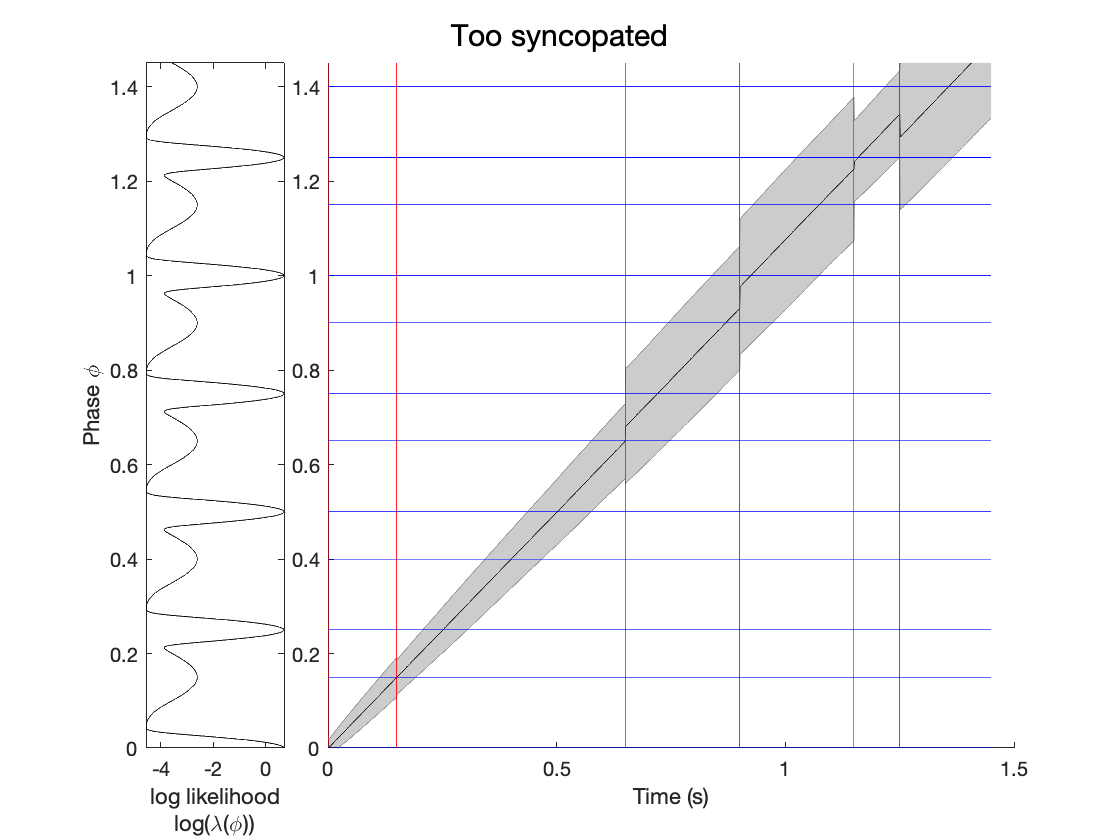


event_times = [0, 0.150, .65, .9, 1.15, 1.25];

params = PIPPET_params(...
    'events_unit', [0, .15],...
    'variance_unit', [.0001, .001],...
    'lambda_unit', [.05, .005],...
    'expected_cycles', 6,...
    'event_times', event_times, ...
    'title', 'Too syncopated');

[mu_list, C_list] = run_PIPPET(params);

## In seven

The filter detects and adjusts to a phase shift in a 7/8 groove.

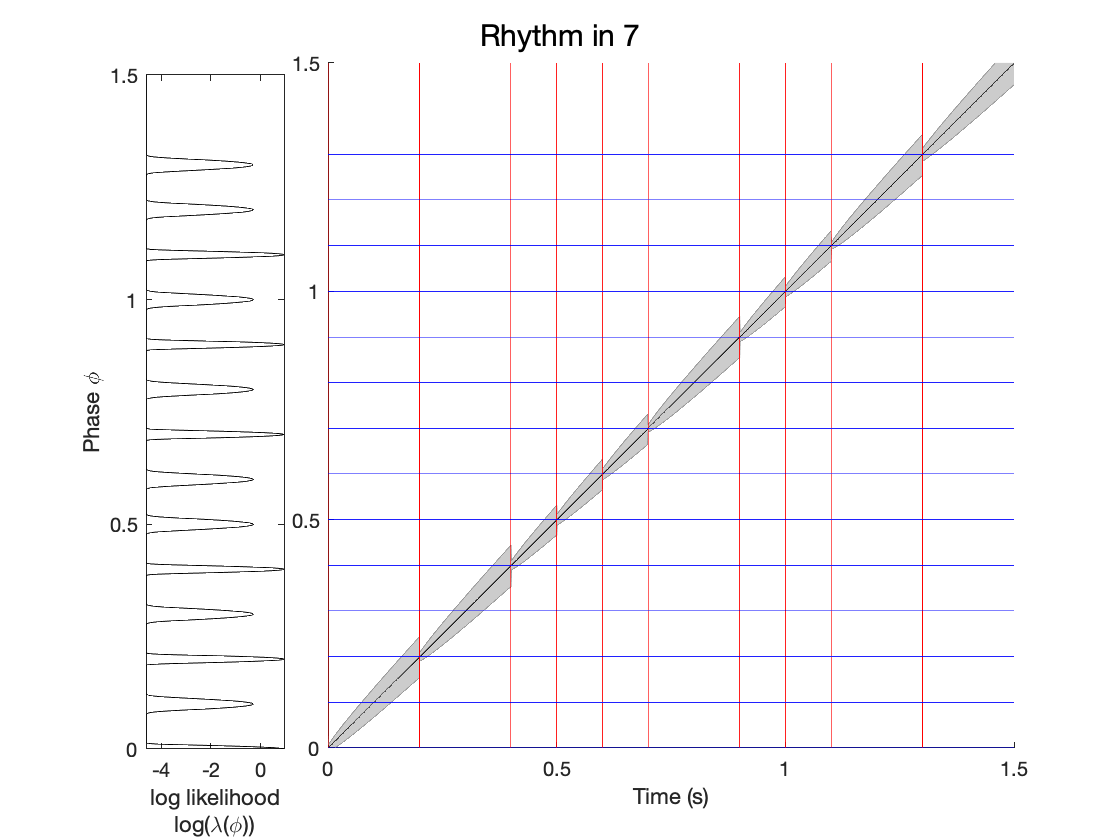


event_times = [0, .2, .4, .5, .6, .7, .9, 1, 1.1, 1.3];

params = PIPPET_params(...
    'events_unit', 0:.1:.6,...
    'variance_unit', [.00001, .00003, .00001, .00003, .00001, .00003, .00003],...
    'lambda_unit', [.02, .01,.02, .01,.02, .01,.01],...
    'expected_cycles', 2,...
    'expected_period', .7,...
    'event_times', event_times, ...
    'title', 'Rhythm in 7');
[mu_list, C_list] = run_PIPPET(params);

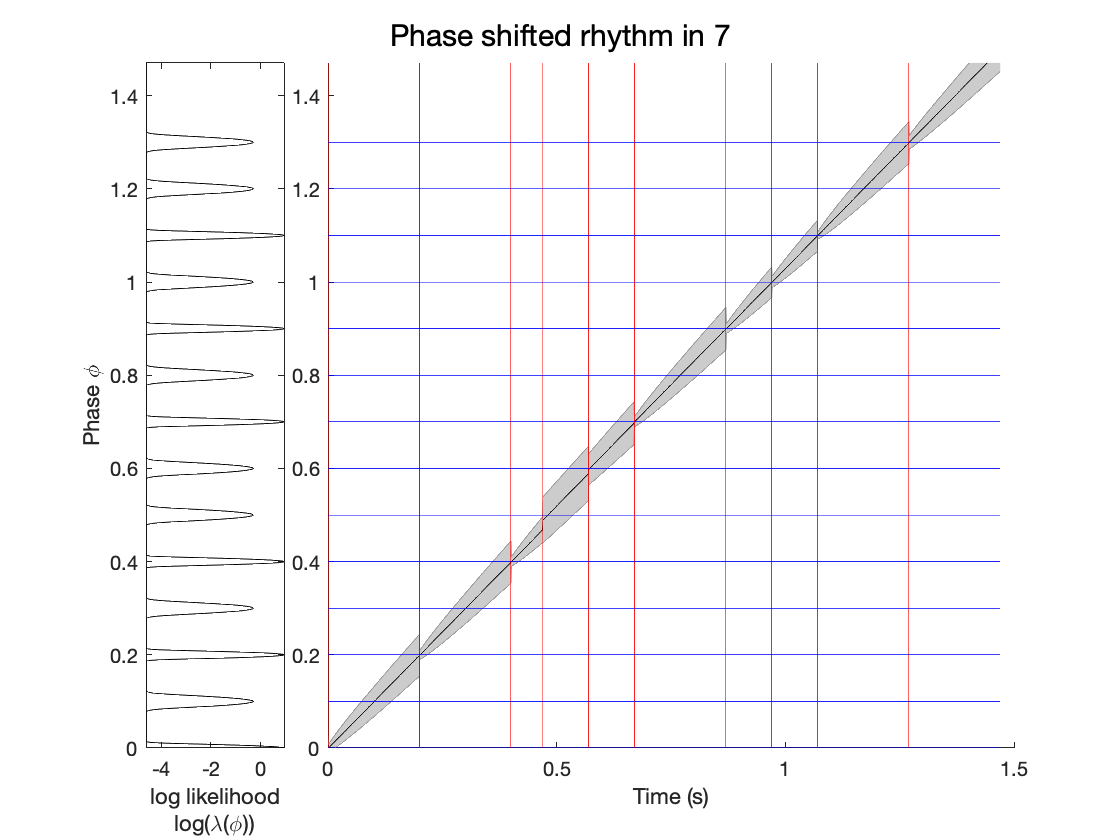



event_times(4:end)=event_times(4:end)-.03;

params = PIPPET_params(...
    'events_unit', 0:.1:.6,...
    'variance_unit', [.00001, .00003, .00001, .00003, .00001, .00003, .00003],...
    'lambda_unit', [.02, .01,.02, .01,.02, .01,.01],...
    'expected_cycles', 2,...
    'expected_period', .7,...
    'event_times', event_times, ...
    'title', 'Phase shifted rhythm in 7');
[mu_list, C_list] = run_PIPPET(params);

## Tapping: autocorr

We introduce a tapping finger that aims to tap with the metronome but introduces motor noise. This tap is used as a second sensory stream for phase estimation. We calculate autocorrelation to determine the phase correction response as it corrects motor noise, and we compare it to the phase correction response to a phase shift.

n_events = 100;

gauss_distribution = @(x, mean, v) exp(-.5 * ((x - mean).^ 2) ./ v)./ (sqrt(2*pi*v));

e_means = 1:n_events;
e_vars = .0001*ones(1,n_events);
e_lambdas = .02*ones(1,n_events);
lambda_0 = .00001;

tap_vars = .0005*ones(1,n_events);
tap_lambdas = .02*ones(1,n_events);
tap_lambda_0 = .00001;
tap_noise = .02;

mu_i_list = @(mu, C) (mu/C + e_means./e_vars)./(1/C + 1./e_vars);
C_i_list = @(C) 1./(1/C + 1./e_vars);
Lambda_i_list = @(mu, C) e_lambdas .* gauss_distribution(mu, e_means, e_vars+C);
Lambda_star = @(mu, C) lambda_0 + sum(Lambda_i_list(mu, C));
mu_star = @(mu, C) (lambda_0*mu + sum(Lambda_i_list(mu, C) .* mu_i_list(mu,C)))/Lambda_star(mu,C);
C_star= @(mu,C) (lambda_0*C + sum(Lambda_i_list(mu, C) .* (C_i_list(C) + (mu_i_list(mu, C)-mu).^2)))/Lambda_star(mu,C);


tap_mu_i_list = @(mu, C) (mu/C + e_means./tap_vars)./(1/C + 1./tap_vars);
tap_C_i_list = @(C) 1./(1/C + 1./tap_vars);
tap_Lambda_i_list = @(mu, C) tap_lambdas .* gauss_distribution(mu, e_means, tap_vars+C);
tap_Lambda_star = @(mu, C) tap_lambda_0 + sum(tap_Lambda_i_list(mu, C));
tap_mu_star = @(mu, C) (tap_lambda_0*mu + sum(tap_Lambda_i_list(mu, C) .* tap_mu_i_list(mu,C)))/tap_Lambda_star(mu,C);
tap_C_star= @(mu,C) (tap_lambda_0*C + sum(tap_Lambda_i_list(mu, C) .* (tap_C_i_list(C) + (tap_mu_i_list(mu, C)-mu).^2)))/tap_Lambda_star(mu,C);


t_max = n_events+5;
dt = 0.01;
t_list = 0:dt:t_max;


template = zeros(length(t_list));
for i = 1:length(e_means)
    template = template + e_lambdas(i)*gauss_distribution(t_list, e_means(i), e_vars(i))';
end
template = template + lambda_0;


mu_list = zeros(size(t_list));
mu_list(1) = 0;

C_list = zeros(size(t_list));
C_list(1) = .0002;

sigma = 0.1;

event_times = e_means;
tap_times = [];

event_num = 1;
next_tap = -1;

for i=2:length(t_list)
    t = t_list(i);
    
    t_past = t_list(i-1);
    C_past = C_list(i-1);
    mu_past = mu_list(i-1);
    dmu = dt*(1 - Lambda_star(mu_past, C_past)*(mu_star(mu_past, C_past)-mu_past));
    dC = dt*(sigma^2 - Lambda_star(mu_past, C_past)*(C_star(mu_past, C_past)-C_past));
    mu = mu_past+dmu;
    C = C_past+dC;
    
    
    if event_num<=length(event_times) && (t>=event_times(event_num) & t_past<event_times(event_num))
        
        mu = mu_star(mu, C);
        C = C_star(mu, C);
        event_num = event_num+1;
    end
    
    if t>=next_tap & t_past<next_tap
        
        mu = tap_mu_star(mu, C);
        C = tap_C_star(mu, C);
        tap_times(end+1) = t;
    end
    
    if floor(mu_list(i-1)-.5) < floor(mu-.5)
        next_tap = t+.5+ tap_noise*randn();
    end
    
    mu_list(i) = mu;
    C_list(i) = C;
end

async = tap_times(1:length(event_times)) - event_times;
AC = autocorr(async)

AC =     1.0000    0.6580    0.4729    0.2721    0.1228    0.1590    0.1359    0.1660    0.1824    0.1195    0.1515    0.1158    0.1054    0.0808    0.0822    0.0361   -0.0104   -0.0891   -0.1129   -0.1334   -0.1544


alpha = 1-AC(2)

alpha = 0.3420

## Tapping: phase shift

The phase correction response to a phase shift, with same parameters as above (minus motor noise)

n_events = 10;
phase_shift = 0.05;

gauss_distribution = @(x, mean, v) exp(-.5 * ((x - mean).^ 2) ./ v)./ (sqrt(2*pi*v));

e_means = 1:n_events;
e_vars = .0001*ones(1,n_events);
e_lambdas = .02*ones(1,n_events);
lambda_0 = .00001;

tap_vars = .0005*ones(1,n_events);
tap_lambdas = .02*ones(1,n_events);
tap_lambda_0 = 0;
tap_noise = 0;

mu_i_list = @(mu, C) (mu/C + e_means./e_vars)./(1/C + 1./e_vars);
C_i_list = @(C) 1./(1/C + 1./e_vars);
Lambda_i_list = @(mu, C) e_lambdas .* gauss_distribution(mu, e_means, e_vars+C);
Lambda_star = @(mu, C) lambda_0 + sum(Lambda_i_list(mu, C));
mu_star = @(mu, C) (lambda_0*mu + sum(Lambda_i_list(mu, C) .* mu_i_list(mu,C)))/Lambda_star(mu,C);
C_star= @(mu,C) (lambda_0*C + sum(Lambda_i_list(mu, C) .* (C_i_list(C) + (mu_i_list(mu, C)-mu).^2)))/Lambda_star(mu,C);


tap_mu_i_list = @(mu, C) (mu/C + e_means./tap_vars)./(1/C + 1./tap_vars);
tap_C_i_list = @(C) 1./(1/C + 1./tap_vars);
tap_Lambda_i_list = @(mu, C) tap_lambdas .* gauss_distribution(mu, e_means, tap_vars+C);
tap_Lambda_star = @(mu, C) tap_lambda_0 + sum(tap_Lambda_i_list(mu, C));
tap_mu_star = @(mu, C) (tap_lambda_0*mu + sum(tap_Lambda_i_list(mu, C) .* tap_mu_i_list(mu,C)))/tap_Lambda_star(mu,C);
tap_C_star= @(mu,C) (tap_lambda_0*C + sum(tap_Lambda_i_list(mu, C) .* (tap_C_i_list(C) + (tap_mu_i_list(mu, C)-mu).^2)))/tap_Lambda_star(mu,C);


t_max = n_events + 2;
dt = 0.001;
t_list = 0:dt:t_max;


template = zeros(length(t_list));
for i = 1:length(e_means)
    template = template + e_lambdas(i)*gauss_distribution(t_list, e_means(i), e_vars(i))';
end
template = template + lambda_0;


mu_list = zeros(size(t_list));
mu_list(1) = 0;

C_list = zeros(size(t_list));
C_list(1) = .0002;

sigma = 0.1;

event_times = e_means;
event_times(5:end) = event_times(5:end) - phase_shift;
tap_times = [];

event_num = 1;
next_tap = -1;

for i=2:length(t_list)
    t = t_list(i);
    
    t_past = t_list(i-1);
    C_past = C_list(i-1);
    mu_past = mu_list(i-1);
    dmu = dt*(1 - Lambda_star(mu_past, C_past)*(mu_star(mu_past, C_past)-mu_past));
    dC = dt*(sigma^2 - Lambda_star(mu_past, C_past)*(C_star(mu_past, C_past)-C_past));
    mu = mu_past+dmu;
    C = C_past+dC;
    
    
    if event_num<=length(event_times) && (t>=event_times(event_num) & t_past<event_times(event_num))
        
        mu = mu_star(mu, C);
        C = C_star(mu, C);
        event_num = event_num+1;
    end
    
    if t>=next_tap & t_past<next_tap
        
        mu = tap_mu_star(mu, C);
        C = tap_C_star(mu, C);
        tap_times(end+1) = t;
    end
    
    if floor(mu_list(i-1)-.5) < floor(mu-.5)
        next_tap = t+.5+ tap_noise*randn();
    end
    
    mu_list(i) = mu;
    C_list(i) = C;
end

async = tap_times(1:length(event_times)) - event_times

async =     0.0010         0         0         0    0.0500    0.0280    0.0130    0.0040    0.0010    0.0010


alpha = 1-(async(6)/async(5));


